# Puma 'FKINE' and plot functions

Author: 

MatlaDrive Link: 

Deliver:

- Assemble the  Robot  using the links of the puma, based on the STL parts given.

- Let us try to animate some links

## Model to be followed

Use DH parameters from Standard convection of Puma560

Loading STL models from ARTE Robotics Toolbox for Education  by Arturo Gil (http://arvc.umh.es/arte).......


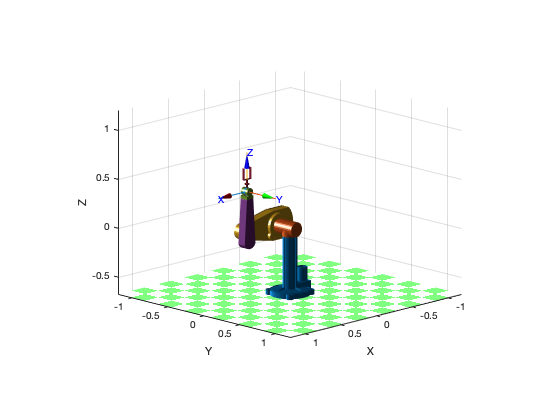

mdl_puma560
p560.plot3d([0 0 0 0 0 0])

p560

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Puma Links

### Link 0

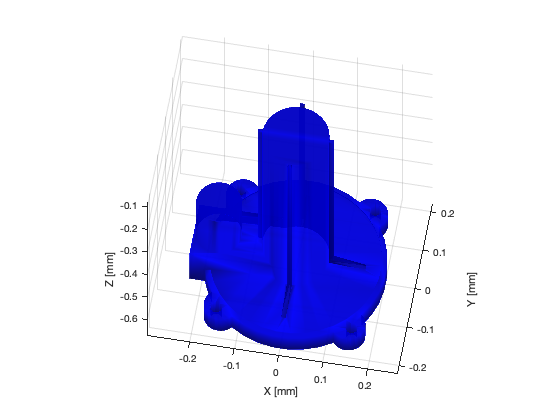

figure
[V,F, N,name]=stlRead('link0.stl');
FVsPlot(F,V,[0 0 1])
axis equal
view(10, 60)

### Link 1

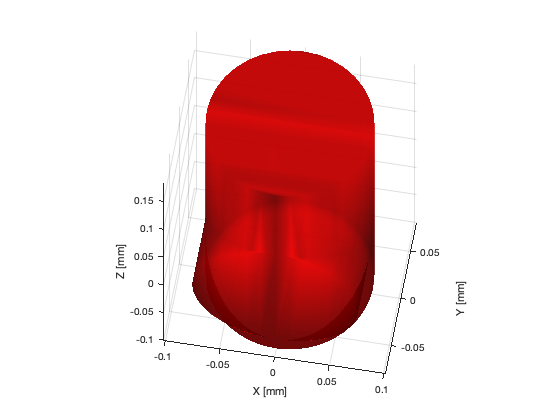

figure
[V,F, N,name]=stlRead('link1.stl');
FVsPlot(F,V,[1 0 0])
axis equal
view(10, 60)

### Link 2

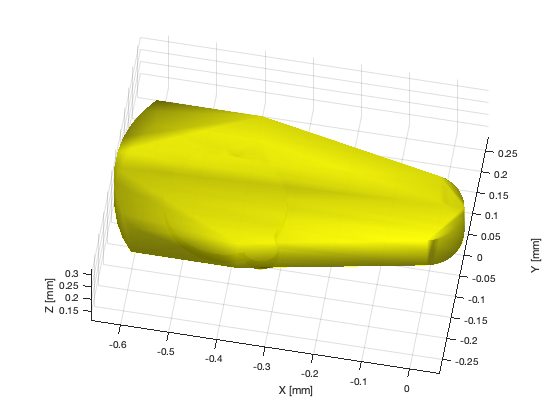

figure
[V,F, N,name]=stlRead('link2.stl');
FVsPlot(F,V,[1 1 0])
axis equal
view(10, 60)

### Link 3

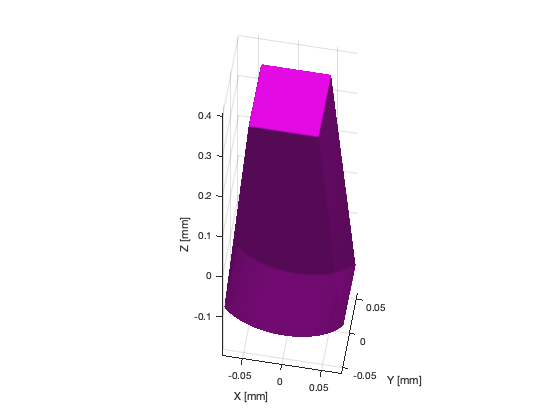

figure
[V,F, N,name]=stlRead('link3.stl');
FVsPlot(F,V,[1 0 1])
axis equal
view(10, 60)

### Link 4

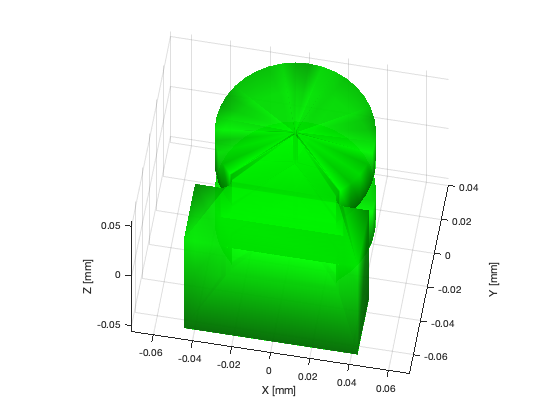

figure
[V,F, N,name]=stlRead('link4.stl');
FVsPlot(F,V,[0 1 0])
axis equal
view(10, 60)

### Link 5

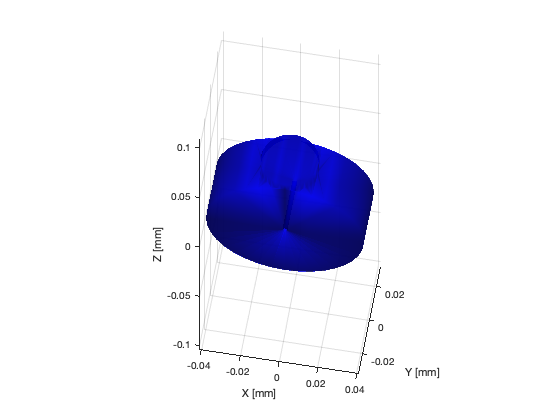

figure
[V,F, N,name]=stlRead('link5.stl');
FVsPlot(F,V,[0 0 1])
axis equal
view(10, 60)

### Link 6

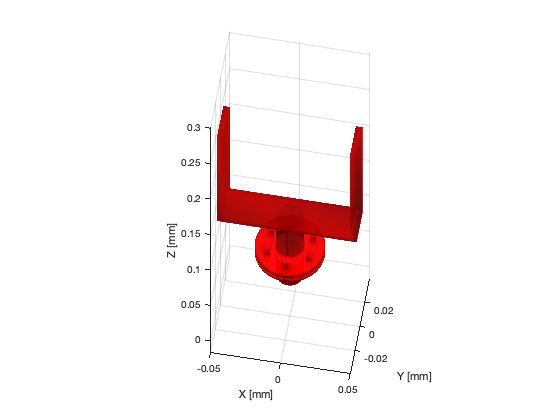

figure
[V,F, N,name]=stlRead('link6.stl');
FVsPlot(F,V,[1 0 0])
axis equal
view(10, 60)

## Plot function

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
end